# Particle Tracking

load('../2018/data/SinkSource.mat')
load('../2018/data/Density_inference.mat','data');
load('../2018/data/Density_estimationMap','g','gd');
load('../2018/data/Flight_estimationMap','guv');
addpath('../2018/functions/')


This code is taken from SinkSource.mlx to generate vy, vx and rho. 

vy = nan(g.nlat, g.nlon, gext.nt); vx=vy; rho = vy;
tmp = repmat(g.latlonmask,1,1,gext.nt); tmp(:,:,ismember(gext.time,g.day-.5))=false;
vy(tmp) = guv.v_est/1000*60*60; % m/s -> km/h (+) north, (-) south
vx(tmp) = guv.u_est/1000*60*60; % m/s -> km/h (+) east, (-) west

tmp2 = gd.dens_est; % bird/km^2 .* repmat(area(g.latlonmask),1,g.nt); % bird
tmp2(g.rain(repmat(g.latlonmask,1,1,g.nt))>data.mask_rain_thr) = 0;
rho(tmp) = tmp2;

dt = 15/60;
dy = lldistkm([g.lat(1) g.lon(1)],[g.lat(2) g.lon(1)]);
dx = lldistkm([g.lat2D(:,1) g.lon2D(:,1)],[g.lat2D(:,1) g.lon2D(:,2)]);
area = repmat(dx*dy,1,g.nlon);

gext_latlonmask2 = conv2(gext.latlonmask, [1 1 1;1 1 1;1 1 1],'same')>0;

vypad = padarray(vy,[1 1 0],nan);
vypad = nanmean(cat(4, fillmissing(vypad,'nearest',2), fillmissing(vypad,'nearest',1)),4);
vypad = fillmissing(vypad,'nearest');
vypad(repmat(~gext_latlonmask2,1,1,gext.nt)) = nan;
F_vlat=griddedInterpolant({1:gext.nlat,1:gext.nlon,1:gext.nt},vypad,'nearest','nearest');

vxpad = padarray(vx,[1 1 0],nan);
vxpad = nanmean(cat(4, fillmissing(vxpad,'nearest',2), fillmissing(vxpad,'nearest',1)),4);
vxpad = fillmissing(vxpad,'nearest');
vxpad(repmat(~gext_latlonmask2,1,1,gext.nt)) = nan;
F_vlon=griddedInterpolant({1:gext.nlat,1:gext.nlon,1:gext.nt},vxpad,'nearest','nearest');

Flandpad = padarray(-W.landing./ (rho(:,:,1:end-1) .* repmat(area,1,1,gext.nt-1)) ,[1 1 0],nan);
Flandpad = nanmean(cat(4, fillmissing(Flandpad,'nearest',2), fillmissing(Flandpad,'nearest',1)),4);
Flandpad = fillmissing(Flandpad,'nearest');
Flandpad(repmat(~gext_latlonmask2,1,1,gext.nt-1)) = nan;
Flandpad(isnan(Flandpad))=0;
F_land=griddedInterpolant({1:gext.nlat,1:gext.nlon,1:gext.nt-1},Flandpad,'nearest');

F_out = griddedInterpolant({1:gext.nlat,1:gext.nlon},padarray(double(g.latlonmask),[1 1],0),'nearest','none');

Wind field

load('data/Wind_estimationMap')

wlat = nan(g.nlat, g.nlon, gext.nt); wlon=wlat;
tmp = repmat(g.latlonmask,1,1,gext.nt); tmp(:,:,ismember(gext.time,g.day-.5))=false;
wlat(tmp) = gwuv.v_est/1000*60*60; % m/s -> km/h (+) north, (-) south
wlon(tmp) = gwuv.u_est/1000*60*60; % m/s -> km/h (+) east, (-) west

F_wlat=griddedInterpolant({1:g.nlat,1:g.nlon,1:gext.nt},wlat,'nearest');
F_wlon=griddedInterpolant({1:g.nlat,1:g.nlon,1:gext.nt},wlon,'nearest');

Figure

Wind analysis is done in a seperate file

tmp_b = sqrt( (vy-wlat).^2 + (vx-wlon).^2 );
tmp_g = sqrt( (vy).^2 + (vx).^2 );

figure('position',[0 0 1000 400]);
id = g.time_b == 1;
subplot(2,2,1);
[Y,E] = discretize(reshape(tmp_g(:,:,id),[],1),100);
tmp3 = splitapply(@nansum,reshape(rho(:,:,id),[],1),Y);
bar(E(1:end-1)*1000/60/60,tmp3); xlim([0 30])
xlabel('Ground flight speed [m/s]');
ylabel('Number of bird')

subplot(2,2,2);
[Y,E] = discretize(reshape(tmp_b(:,:,id),[],1),80);
tmp3 = splitapply(@nansum,reshape(rho(:,:,id),[],1),Y);
 bar(E(1:end-1)*1000/60/60,tmp3); xlim([0 30])
xlabel('Bird flight speed [m/s]');
ylabel('Number of bird')

id = g.time_b == 3;
subplot(2,2,3);
[Y,E] = discretize(reshape(tmp_g(:,:,id),[],1),100);
tmp3 = splitapply(@nansum,reshape(rho(:,:,id),[],1),Y);
bar(E(1:end-1)*1000/60/60,tmp3); xlim([0 30])
xlabel('Ground flight speed [m/s]');
ylabel('Number of bird')

subplot(2,2,4);
[Y,E] = discretize(reshape(tmp_b(:,:,id),[],1),100);
tmp3 = splitapply(@nansum,reshape(rho(:,:,id),[],1),Y);
 bar(E(1:end-1)*1000/60/60,tmp3); xlim([0 30])
xlabel('Bird flight speed [m/s]');
ylabel('Number of bird')
for i_d=1:numel(g.day_b)
    id = g.day_id==i_d;
    tmp = tmp_b(:,:,id) .* rho(:,:,id);
    tmp3 = tmp_g(:,:,id) .* rho(:,:,id);
    tmp2 = rho(:,:,id);
    vbday(i_d) = nansum(tmp(:)) / nansum(tmp2(:));
    vgday(i_d) = nansum(tmp3(:)) / nansum(tmp2(:));
end
figure('position',[0 0 1000 400]); hold on;
plot( g.day, vbday*1000/60/60 )
plot( g.day, vgday*1000/60/60 )
ylabel('Flight Speed [m/s]');
legend('Bird', 'Ground')

Preperation for energy

Sp = table();
Sp.name = {'Willow Warbler'	'Tree Pipit'	'Common Chiffchaff'	'Spotted Flycatcher'	'Garden Warbler'	'Common Whitethroat'	'European Pied Flycatcher'	'Common Redstart'	'Wood Warbler'	'Eurasian Blackcap'}';
Sp.massmin = [8 	20	6	13	16	12	9	12	7	14]';
Sp.massmax = [10	25	9	19	23	18	15	20	12	20]';
Sp.wingmin = [17	25	15	23	20	19	22	21	20	22]';
Sp.wingmax = [22	27	21	25	24	23	24	24	24	24]';
Sp.abondance = [27.5	12.7	11.3	8.7	7.3	7.1	6.8	6.6	6.1	5.9]';

Parameter for energy speding

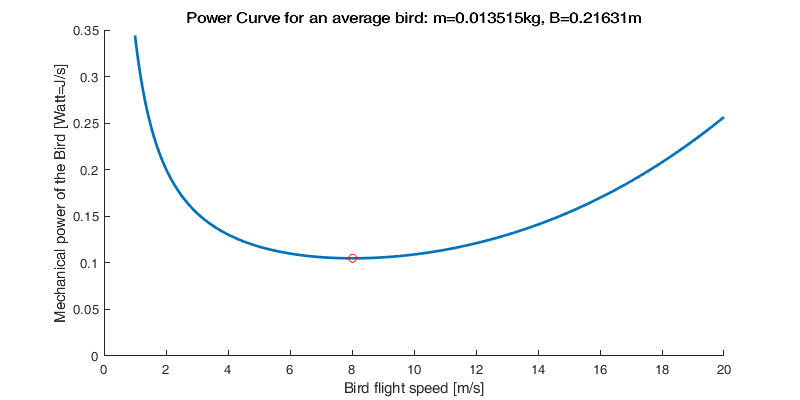

k=1.2; % [-] Induced power factor (p. 45).
m = sum((Sp.massmin+Sp.massmax)/2.*Sp.abondance/100)/1000; % [kg] mass of bird. Values found in appendix of (Aurbach et al., 2020)
gcst = 9.81; % [ms-2] gravity constant
% Vt [m/s] true speed (bird speed-wind speed)
B = sum((Sp.wingmin+Sp.wingmax)/2.*Sp.abondance/100)/100;% [m] Wing span. Values found in appendix of (Aurbach et al., 2020)
airdens = 1; % Air density ?
Sb = 0.00813*m^0.666; % [m2] body frontal area
CDb = 0.1; % [-] body drag coefficient (p. 51).
Cpro = 8.4;
Ra = 7;

f_eng = @(Vt) (2*k*(m*gcst)^2)./(Vt*pi*B.^2*airdens) + airdens*Vt.^3*Sb*CDb/2 + Cpro/Ra*1.05*k^(3/4)*m^(3/2)*gcst^(3/2)*Sb^(1/4)*CDb^(1/4)/airdens^(1/2)/B^(3/2);

figure('position',[0 0 800 400]); hold on;
vt=1:0.01:20; Pvt = f_eng(vt);
plot(vt, Pvt,'LineWidth',2)
[~, tmp] = min(Pvt); plot(vt(tmp),min(Pvt),'or')
xlabel('Bird airspeed [m/s]'); ylabel('Mechanical power of the Bird [Watt=J/s]'); 
title(['Power Curve for an average bird: m=' num2str(m) 'kg, B=' num2str(B) 'm']);
ylim([0 0.35])

Figure

% tmp_b = sqrt( (vlat-wlat).^2 + (vlon-wlon).^2 );
% tmp_g = sqrt( (vlat).^2 + (vlon).^2 );
% 
% EN = f_eng(tmp_b*1000/60/60); %  km/h*m/km*s/h ->m/s   J/s 
% ENkm = EN ./ (tmp_g/60/60); % J/s / (km/h*s/h ) -> J/km
% 
% clear tmp3
% for i_d=1:numel(g.day_b)
%     id = g.day_id==i_d;
%     tmp = ENkm(:,:,id) .* rho(:,:,id);
%     tmp2 = rho(:,:,id);
%     tmp3(i_d) = nansum(tmp(:)) / nansum(tmp2(:));
% end
% figure('position',[0 0 1000 400]); 
% plot( g.day, tmp3)
% ylabel('Average Energy speng per km [J/km]');
% yyaxis right
% plot( g.day, Ts.day.departure )
% ylabel('Nb of bird departing');
% figure;plot(Ts.day.departure, tmp3,'.')

Preparation to save flight duration and distances

flight_duration_bins=-.125:dt:15.125;
flight_duration = nan(g.nat-1, numel(flight_duration_bins)-1);
flight_distance_bins=-5:10:1005;
flight_distance = nan(g.nat-1, numel(flight_distance_bins)-1);
energy_bins=0:100:10000;
energy = nan(g.nat-1, numel(energy_bins)-1);
energykm_bins=0:.1:20;
energykm = nan(g.nat-1, numel(energykm_bins)-1);

Number of bird to simulate: 1 for every `r`

r = 1000; % 1 for every 1000.
% Ts_day_departure_sim=1000*ones(g.nat-1,1); % Fixte number
% Old version with a W.day.departure unknown... Ts.day.departure = reshape(nansum(nansum(W.day.departure,1),2),1,[]);
Ts_day_departure_sim = round((Ts.Fout.day.entering + Ts.day.takingoff)/r);
Ts_day_departure_sim(isnan(Ts_day_departure_sim))=0;
knownday = ismember(datenum(g.day), unique(data.day(data.day_id)));

for i_day=1:g.nat
    
    % Find the time of the night
    idt=find(gext.day_id(1:end-1)==i_day);
    
    % Old version with a W.departure unknown... tmp = W.departure(:,:,idt);
    tmp = Fout.entering(:,:,idt);
    tmp(2:end-1,2:end-1,:) = tmp(2:end-1,2:end-1,:)+W.takingoff(:,:,idt);
   

    y = randsample(numel(tmp(:)), Ts_day_departure_sim(i_day), true, tmp(:));
    
    y_lat = nan(Ts_day_departure_sim(i_day), numel(idt)); y_lon=y_lat;
    [y_lat(:,2), y_lon(:,2), y_t] = ind2sub(size(tmp),y);
    
    En = zeros(Ts_day_departure_sim(i_day), 1);
    
    y_t=y_t+1;
    
    for i_t=2:numel(idt)
        % Find bird in the air
        id = (y_t <= i_t);
     
        % Find if bird lands until next step (no need to move them forward)
        landing = F_land(y_lat(:, i_t), y_lon(:, i_t), repmat(idt(i_t-1),Ts_day_departure_sim(i_day),1))>rand(Ts_day_departure_sim(i_day),1);
        y_t(id & landing)=Inf;
        id(landing)=false;
        
        % Find the speed
        v_lat = F_vlat(y_lat(id, i_t), y_lon(id, i_t), repmat(idt(i_t),sum(id),1)); % km/h
        v_lon = F_vlon(y_lat(id, i_t), y_lon(id, i_t), repmat(idt(i_t),sum(id),1)); % km/h
        
        % Compute energy
        Vt = sqrt( (v_lat-F_wlat(y_lat(id, i_t), y_lon(id, i_t), repmat(idt(i_t),sum(id),1))).^2  +  (v_lon - F_wlon(y_lat(id, i_t), y_lon(id, i_t), repmat(idt(i_t),sum(id),1))).^2);
        En(id) = En(id) + f_eng(Vt*1000/60/60)*60*15; % Vt is in km/h -> m/s for f_eng. Puis, J/s -> J [15min]
        
        % Update position
        y_lat(id, i_t+1) = y_lat(id, i_t) + v_lat*dt/dy;
        y_lon(id, i_t+1) = y_lon(id, i_t) + v_lon.*dt./interp1((1:g.nlat)',dx,y_lat(id, i_t),'linear','extrap');
        
        % keep same position for that have not yet left
        y_lat(~id, i_t+1) = y_lat(~id, i_t);
        y_lon(~id, i_t+1) = y_lon(~id, i_t); 

        % Check for errors
        % assert(~any(isnan(y_lon(:, i_t+1))))
        y_lat(isnan(y_lat(:, i_t+1)), i_t+1) = y_lat(isnan(y_lat(:, i_t+1)), i_t);
        y_lon(isnan(y_lon(:, i_t+1)), i_t+1) = y_lon(isnan(y_lon(:, i_t+1)), i_t); 
       
        
        % Check if bird out
        out = ~(F_out(y_lat(:, i_t+1), y_lon(:, i_t+1))==1);
        y_t(out) = 999;
        
    end
    
    % assert(~any(isnan(y_lon(:))))
    assert(all(~y_t<100))
    % Compute stat
    
    % take only bird that have not left the system
    id2 = y_t~=999;
    
    
    % Average duration
    flight_duration(i_day,:) = histcounts(sum(~(diff(y_lon(id2,:),1,2)==0),2)*dt, flight_duration_bins);
    
    % Average distance
    fd=nan(Ts_day_departure_sim(i_day),1);
    for i_b=1:Ts_day_departure_sim(i_day)
        lon = interp1(1:g.nlon,g.lon,unique(y_lon(i_b,:),'stable'))';
        lat = interp1(1:g.nlat,g.lat,unique(y_lat(i_b,:),'stable'))';
        if numel(lon)==1
            fd(i_b) = 0;
        else
            fd(i_b) = sum(lldistkm([lat(2:end-1) lon(2:end-1)],[lat(3:end) lon(3:end)]));
        end
    end
    flight_distance(i_day,:) = histcounts(fd(id2), flight_distance_bins);
    
    % Average Energy
    energy(i_day,:) = histcounts(En(id2), energy_bins);
    energykm(i_day,:) = histcounts(En(id2)./fd(id2), energykm_bins);
    
    if (Ts_day_departure_sim(i_day)>0)
        origin = sub2ind([gext.nlat gext.nlon],round(y_lat(:,2)),round(y_lon(:,2)));
        dest = sub2ind([gext.nlat gext.nlon],round(y_lat(:,i_t+1)),round(y_lon(:,i_t+1)));
        [C,~,ic] = unique([origin dest],'rows');
        res{i_day} = [C splitapply(@sum,ones(numel(ic),1),ic)*r];
    else
        res{i_day} = nan(0,3);
    end
end

Figure: movement during one night;

% figure;
% h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
% setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
% geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
% for i_b=1:100
%     plotm(interp1(1:g.nlat,g.lat,y_lat(i_b,:)), interp1(1:g.nlon,g.lon,y_lon(i_b,:)),'-k')
% end
% plotm(interp1(1:g.nlat,g.lat,y_lat(:,2)), interp1(1:g.nlon,g.lon,y_lon(:,2)),'^k','MarkerFaceColor',[0 0 0])
% plotm(interp1(1:g.nlat,g.lat,y_lat(~(y_t==999),end)), interp1(1:g.nlon,g.lon,y_lon(~(y_t==999),end)),'vk','MarkerFaceColor',[0 0 0])
% plotm(interp1(1:g.nlat,g.lat,y_lat(y_t==999,end)), interp1(1:g.nlon,g.lon,y_lon(y_t==999,end)),'<k','MarkerFaceColor',[1 0 0])


Figure: Movement of a bird during the night

% filename='data/Density_estimationMap_M';
%filename='data/Density_estimationMap_M';
i_day=245;
figure(3); 
ii=4;
idtt = idt(3:ii:end-1);
rng('default')
tmp = datasample(find(abs(y_lat(:,2)-y_lat(:,end))>2),7);
y_latt = interp1(1:gext.nlat,gext.lat,y_lat(tmp,3:ii:end));
y_lont = interp1(1:gext.nlon,gext.lon,y_lon(tmp,3:ii:end));
%col = get(gca,'colororder');

s=ones(numel(tmp),1); % 1: ground, 2: departure, 3: in air, 4: landing 5: landed

for i_t = 1:numel(idtt)
    s(s==2)=3;
    s(s==4)=5;
    s(s==1 & y_latt(:,i_t)~=y_latt(:,i_t+1))=2;
    s(s==3 & y_latt(:,i_t)==y_latt(:,i_t+1))=4;
    
    subplot(3,numel(idtt),i_t)
    h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [77 77 77]./255); 
    set(gcf,'color','w'); colormap(gca,brewermap([],'Spectral')); caxis([-5000 5000]); 
    title(datestr(gext.time(idtt(i_t)),'HH:MM'),'FontSize',14);
    tmp=W.takingoff(:,:,idtt(i_t)); tmp(tmp<0.001)=nan;
    hsurf=surfm(g.lat2D,g.lon2D,tmp);
    scatterm(y_latt(s==1,i_t),y_lont(s==1,i_t),[],col(s==1,:),'.')
    scatterm(y_latt(s==2,i_t),y_lont(s==2,i_t),[],col(s==2,:),'filled')
 
    subplot(3,numel(idtt),numel(idtt)+i_t)
    h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [77 77 77]./255);
    gd_tmp = nan(g.nlat, g.nlon);
    gd_tmp(g.latlonmask)=nanmean(gd.dens_est(:,g.time==gext.time(idtt(i_t))),2);
    gd_tmp(gd_tmp==0)=NaN;
    surfm(g.lat2D,g.lon2D,gd_tmp); 
    % plotm(data.lat,data.lon,'.k')
    gu_tmp = nan(g.nlat, g.nlon); gv_tmp = nan(g.nlat, g.nlon);
    gu_tmp(g.latlonmask)=nanmean(guv.u_est(:,g.time==gext.time(idtt(i_t))),2);
    gu_tmp(gu_tmp==0)=NaN;
    gv_tmp(g.latlonmask)=nanmean(guv.v_est(:,g.time==gext.time(idtt(i_t))),2);
    gv_tmp(gv_tmp==0)=NaN;
    quiverm(g.lat2D(1:5:end,1:5:end),g.lon2D(1:5:end,1:5:end),gu_tmp(1:5:end,1:5:end),gv_tmp(1:5:end,1:5:end),'k')
    caxis([0 50])
    for i_s=1:numel(s)
        if (s(i_s)==3)
            plotm(y_latt(i_s,1:i_t)',y_lont(i_s,1:i_t)','LineWidth',2,'Color',col(i_s,:))
        end
    end
    scatterm(y_latt(s==3,i_t),y_lont(s==3,i_t),[],col(s==3,:),'filled')
    
    subplot(3,numel(idtt),2*numel(idtt)+i_t)
    h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [77 77 77]./255);
    set(gcf,'color','w'); colormap(gca,brewermap([],'Spectral')); caxis([-5000 5000]); 
    tmp=W.landing(:,:,idtt(i_t)); tmp(tmp>-10)=nan;
    hsurf=surfm(g.lat2D,g.lon2D,tmp);
    scatterm(y_latt(s==4,i_t),y_lont(s==4,i_t),[],col(s==4,:),'filled')
    scatterm(y_latt(s==5,i_t),y_lont(s==5,i_t),[],col(s==5,:),'.')
 
end


% figure;
% h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
% setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
% geoshow('landareas.shp', 'FaceColor', [77 77 77]./255); 
% plotm(y_latt',y_lont')


Flight duration

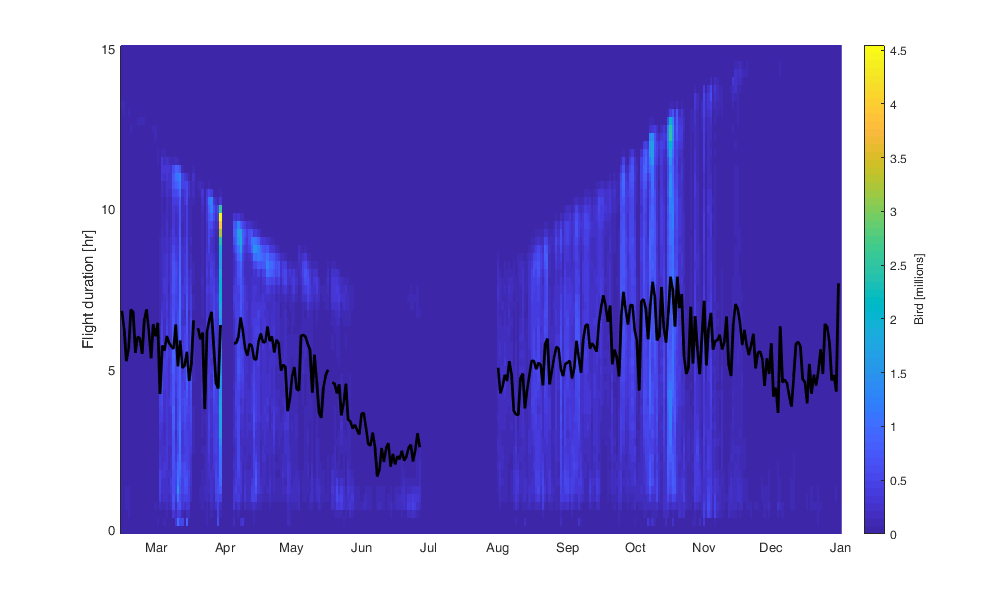

figure('position',[0 0 1000 600]); hold on;
tmp = flight_duration_bins(1:end-1)+diff(flight_duration_bins)/2;
imagesc(datenum(g.day),tmp,flight_duration'/1000);
plot(datenum(g.day),sum( repmat(tmp,g.nat,1).*flight_duration ,2) ./ sum( flight_duration ,2),'-k','Linewidth',2)
datetick('x'); ylabel('Flight duration [hr]'); c=colorbar; c.Label.String='Bird [millions]'; axis tight; set(gca,'ydir','normal');

Flight distance

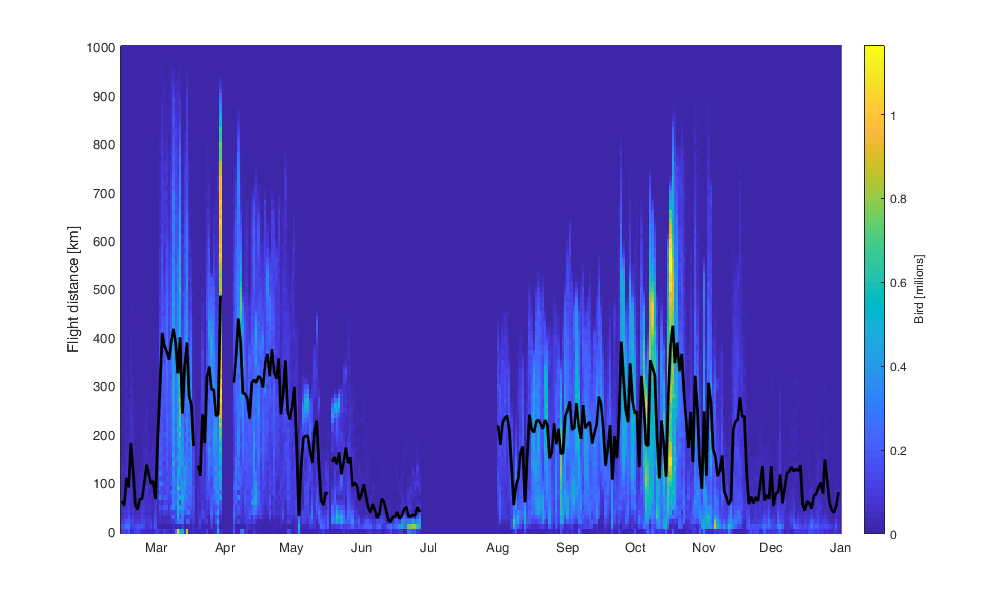

figure('position',[0 0 1000 600]); hold on;
tmp = flight_distance_bins(1:end-1)+diff(flight_distance_bins)/2;
imagesc(datenum(g.day),tmp,flight_distance'/1000);
plot(datenum(g.day),sum( repmat(tmp,g.nat,1).*flight_distance ,2) ./ sum( flight_distance ,2),'-k','Linewidth',2)
datetick('x'); ylabel('Flight distance [km]'); c=colorbar; c.Label.String='Bird [milions]'; axis tight; set(gca,'ydir','normal');

Energy

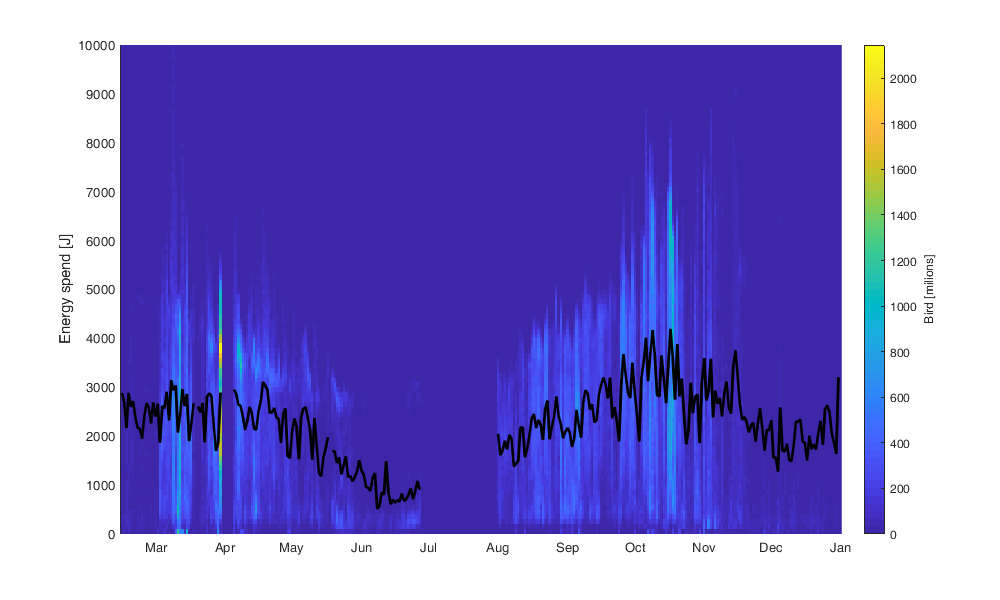

figure('position',[0 0 1000 600]); hold on;
tmp = energy_bins(1:end-1)+diff(energy_bins)/2;
imagesc(datenum(g.day),tmp,energy');
plot(datenum(g.day),sum( repmat(tmp,g.nat,1).*energy ,2) ./ sum( energy ,2),'-k','Linewidth',2)
datetick('x'); ylabel('Energy spend [J]'); c=colorbar; c.Label.String='Bird [milions]'; axis tight; set(gca,'ydir','normal');

Energy per km

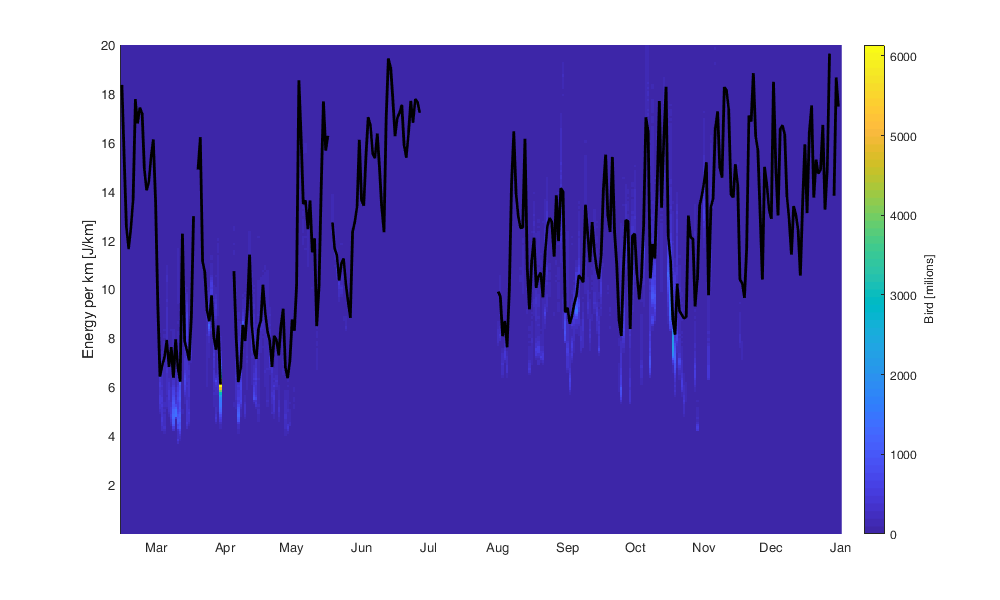

figure('position',[0 0 1000 600]); hold on;
tmp = energykm_bins(1:end-1)+diff(energykm_bins)/2;
imagesc(datenum(g.day),tmp,energykm');
plot(datenum(g.day),sum( repmat(tmp,g.nat,1).*energykm ,2) ./ sum( energykm ,2),'-k','Linewidth',2)
datetick('x'); ylabel('Energy per km [J/km]'); c=colorbar; c.Label.String='Bird [milions]'; axis tight; set(gca,'ydir','normal');

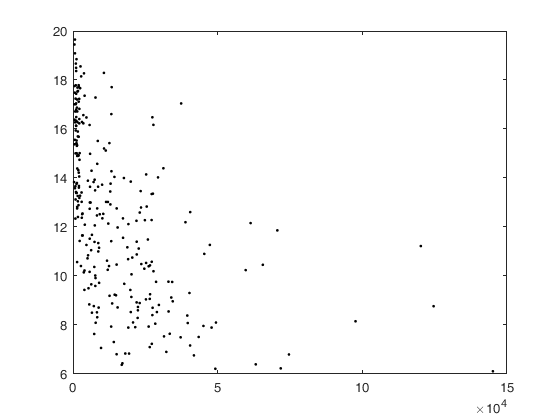

figure; plot(Ts_day_departure_sim,sum( repmat(tmp,g.nat,1).*energykm ,2) ./ sum( energykm ,2),'.k')

## Export for flowmap

Compute the flow table

flows=table('Size',[sum(cellfun('length',res)) 4],'VariableTypes',{'int64','int64','int64','datetime'},'VariableNames',{'origin','dest','count','time'});
i=1;
for i_day=1:g.nat
    id = i:i+size(res{i_day},1)-1;
    flows.origin(id) = res{i_day}(:,1);
    flows.dest(id) = res{i_day}(:,2);
    flows.count(id) = res{i_day}(:,3);
    flows.time(id) = g.day(i_day);
    i=i+size(res{i_day},1);
end

test

flowsMin = flows(flows.time=='14-feb-2018',:);
locationsMin = table((1:numel(gext.lat2D))',string([num2str(gext.lat2D(:),'%2.2f') repmat(', ',numel(gext.lat2D),1) num2str(gext.lon2D(:),'%2.2f')]), gext.lat2D(:), gext.lon2D(:),'VariableNames',{'id','name','lat','lon'});

Downscale the grid by a factor `rll`

rll = 2; 
gflow={};
gflow.lat =  movmean(gext.lat,rll); gflow.lat = gflow.lat(rll:rll:end);

gflow = 1

gflow.lon =  movmean(gext.lon,rll); gflow.lon = gflow.lon(rll:rll:end);
[gflow.lon2D, gflow.lat2D] = meshgrid(gflow.lon,gflow.lat);

Create a match index from the `g.ext` grid to the `g.flow` grid. 

gflow.id = reshape(1:numel(gflow.lat2D),numel(gflow.lat),numel(gflow.lon));
gflow.match = repelem(gflow.id,rll,rll);
gflow.match = [gflow.match nan(size(gflow.match,1),1); nan(1,size(gflow.match,2)+1)];
origin2 = gflow.match(flows.origin);
dest2 = gflow.match(flows.dest);
[~,tmp1,tmp2] = unique([origin2 dest2 datenum(flows.time)],'rows');
flowsMin = flows(tmp1,:);
flowsMin.origin = origin2(tmp1);
flowsMin.dest = dest2(tmp1);
flowsMin.count = accumarray(tmp2,flows.count);
flowsMin(isnan(flowsMin.origin)|isnan(flowsMin.dest),:)=[];
flowsMin(flowsMin.count<5000,:)=[];
flowsMin(flowsMin.origin==flowsMin.dest,:)=[];

locations = table((1:numel(gflow.lat2D))',string([num2str(gflow.lat2D(:),'%2.2f') repmat(', ',numel(gflow.lat2D),1) num2str(gflow.lon2D(:),'%2.2f')]), gflow.lat2D(:), gflow.lon2D(:),'VariableNames',{'id','name','lat','lon'});
tmp = uint64(sort(unique([flowsMin.origin;flowsMin.dest])));
locationsMin = locations(tmp,:);

Write files

flowsMin.time= datestr(flowsMin.time,'yyyy-mm-dd');
writetable(locationsMin,'data/flowmap_locations.csv')
writetable(flowsMin,'data/flowmap_flows.csv')

# Wintering/Breeding model

## Global

Fsi=nansum(Ts.Fout.day.arrival(1:150))/1000000;
Fso=-nansum(Ts.Fout.day.departure(1:150))/1000000;
Fai=nansum(Ts.Fout.day.arrival(150:end))/1000000;
Fao=-nansum(Ts.Fout.day.departure(150:end))/1000000;

Fr=(nansum(Ts.Fout.day.departure)+nansum(Ts.Fout.day.arrival))/1000000;

figure;hold on;
plot(Ts.Fout.day.arrival)
plot(-Ts.Fout.day.departure)
figure;hold on;
plot(cumsum(Ts.Fout.day.arrival,'omitnan')-cumsum(-Ts.Fout.day.departure,'omitnan'))

IN = Ts.Fout.day.arrival/1000000;
IN(isnan(IN))=0;
OUT = -Ts.Fout.day.departure/1000000;
OUT(isnan(OUT))=0;


Nw=nan(g.nat,1); 
Nm=nan(g.nat,1); 
Ns=nan(g.nat,1); 
Nw(1)=300;
Nm(1)=0;
Ns(1)=0;


for i_t=1:150

    % Repartition of arrival betwewen migrant and summuring bird. 
    % prioriginty summering
    arrival_s = min(IN(i_t), Fsi-Ns(i_t));
    arrival_m = IN(i_t)-arrival_s;
    
    % Repartition of departure between migrant and wintering. 
    % Repartition betwewen migrant and summuring bird. 
    departure_w = min(min(OUT(i_t), Fso-Nw(i_t)),Nw(i_t));
    departure_m = OUT(i_t) - departure_w;

    Nw(i_t+1) = Nw(i_t) - departure_w;
    Nm(i_t+1) = Nm(i_t) + arrival_m - departure_m;
    Ns(i_t+1) = Ns(i_t) + arrival_s;
end


figure; hold on;
plot(g.day, Nw)
plot(g.day,Ns)
plot(g.day,Nm)